# MATLAB TD 2

### Nom Complet: Luiz Felipe SPINOLA SILVA

## Exercise 1: Dessin

Lisez l'aide de la fonction plot. A quoi correspondent x et y dans plot(x,y). Ecrire un script qui étant donnés deux entiers a=3 et b=2 permet de tracer un rectangle de largeur a et de longueur b centré en 0 et sur la même figure un cercle de rayon 2*a, également centré en 0. Transformez votre scripte en fonction dessin(a,b)

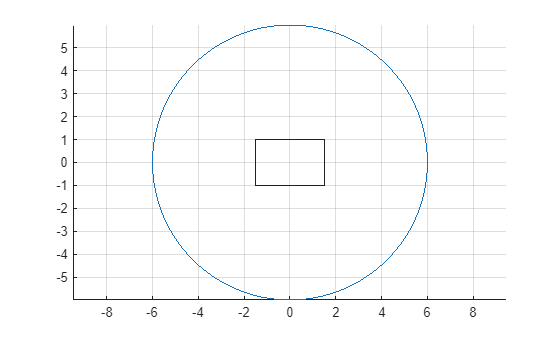

%lisez dessin.m
clc; clear; close all;
a = 3;
b = 2;
figure()
draw = dessin(a, b);
hold off;

## Exercice 2 : Intersection

On considère la fonction g(p)=a*p-b*p^2 pour l'intervalle p=[0,1] contenant 101 points. Tracer sur un même graphe, la fonction g en ligne pleine rouge et la droite y=0.6 en bleu pointillé sachant que a=b=3.5; Lire approximativement les points d'intersections (valeurs de p). Retrouver à l'aide de fonctions matlab les valeurs de p correspondantes en supposant une erreur possible de eps=0.005. Matérialiser ces points sur le graphe de g à l'aide de carrés noirs et sur le graphe de y à l'aide de diamants jaunes, (suffisamment gros!). Trouver le maximum de g et tracer une ligne horizontale passant par ce maximum et une ligne verticale perpendiculaire à l'axe des abscisses passant par ce maximum.

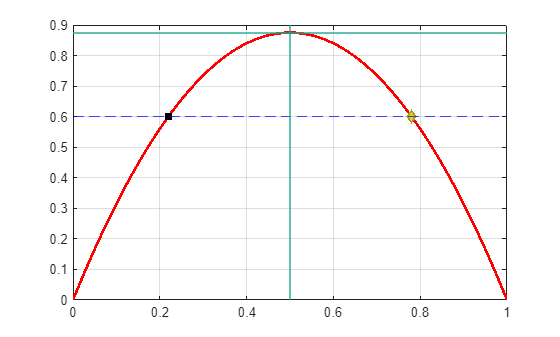

p = linspace(0, 1, 101);
a = 3.5;
b = a;
g = (a.*p) - (b*(p.^2));


figure()
plot(p,g, Color="r", LineWidth=2)
grid on;
yline(0.6, "--", Color="b")
points = p(abs(g - 0.6) < 0.005);
ypoints = g(abs(g - 0.6) < 0.005);
hold on;
plot(points(1), ypoints(1), 'square', 'MarkerFaceColor', 'k', 'MarkerEdgeColor', 'k');
plot(points(2), ypoints(2),"diamond", 'MarkerFaceColor', '#decc2a', 'MarkerEdgeColor', '#a89a1e', 'LineWidth',1.5)
gmax = p(g == max(g(:)));
xline(gmax, Color="#1ea88d", LineWidth= 1.5)
yline(max(g(:)), Color="#1ea88d", LineWidth= 1.5)
hold off

## Exercice 3 : Nombres premiers

Le théorème de Felgner dit que le nième nombre premier pn est toujours supérieur à 0.91nln(n) et inférieur à 1.7nln(n). Mettre dans un tableau tous les nombres premiers <10000 (allez voir l'aide!!!). Donner le nombre de nombres premiers <10000. A l'aide d'un graphe, vérifier la relation de Felgner.

np = primes(10000);
sizenp = size(np);
n = 1:sizenp(2);
min_felgner = 0.91.*n.*log(n)

min_felgner = 1.0e+03 *

         0    0.0013    0.0030    0.0050    0.0073    0.0098    0.0124    0.0151    0.0180    0.0210    0.0240    0.0271    0.0303    0.0336    0.0370    0.0404    0.0438    0.0473    0.0509    0.0545    0.0582    0.0619    0.0656    0.0694    0.0732    0.0771    0.0810    0.0849    0.0889    0.0929    0.0969    0.1009    0.1050    0.1091    0.1132    0.1174    0.1216    0.1258    0.1300    0.1343    0.1386    0.1429    0.1472    0.1515    0.1559    0.1603    0.1647    0.1691    0.1735    0.1780


max_felgner = 1.7.*n.*log(n)

max_felgner = 1.0e+04 *

         0    0.0002    0.0006    0.0009    0.0014    0.0018    0.0023    0.0028    0.0034    0.0039    0.0045    0.0051    0.0057    0.0063    0.0069    0.0075    0.0082    0.0088    0.0095    0.0102    0.0109    0.0116    0.0123    0.0130    0.0137    0.0144    0.0151    0.0159    0.0166    0.0173    0.0181    0.0189    0.0196    0.0204    0.0212    0.0219    0.0227    0.0235    0.0243    0.0251    0.0259    0.0267    0.0275    0.0283    0.0291    0.0299    0.0308    0.0316    0.0324    0.0333


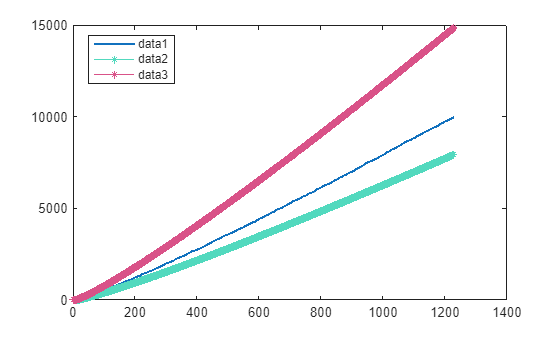

figure()
plot(n,np, LineWidth=1.5)
hold on
plot(n, min_felgner, "Color", "#52d9be", "Marker","*")
plot(n, max_felgner, "Color", "#d95288", "Marker","*")
legend

legend("Position", [0.1572 0.7503 0.1547, 0.1473])
hold off

## Exercice 4 : Signal Sinusoïdal

Donner le graphe d'un signal sinusoïdal de fréquence 1kHz, échantillonné à 2kHz pendant 50 secondes. Donner « l'illusion » d'un mouvement à votre sinusoïde en ajoutant une phase variable entre 0 et 2pi. Utiliser la commande pause lors d'un changement de phase.

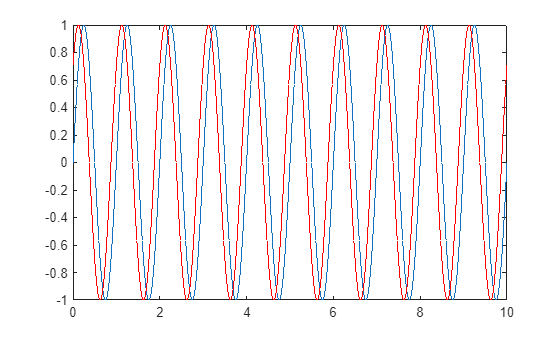

fsample = 2000;                     %Frequência de Amostragem - Hz
time = 0:1/fsample:10;               %Vetor de tempo - s
f = 1;                             %Frequência da Senoide
amp = 1;                            %Amplitude         
th = 0;                             %Fase - rad

s1 = amp*sin(2*pi*f*time + th);
figure()
plot(time, s1)
hold on
th = pi/4;
s1 = amp*sin(2*pi*f*time + th);
plot(time, s1, "red")

## Exercice 5 : Ressort

On considère un ressort que l'on tend et dont on mesure la force à l'aide d'un dynamomètre. L'erreur sur la force est de +1/-0.5 N.

x = [4.2 5.0 6.0 7.0 8.0 9.0 10.0 11.0 12.0 13.0 14.0]; % [cm]

force = [0.0 1.1 2.0 3.2 3.9 4.6 5.8 7.0 8.1 9.0 9.5]; % [N]

Tracer le graphe force=f(longueur) avec les barres d'erreur (aide matlab: errorbar)

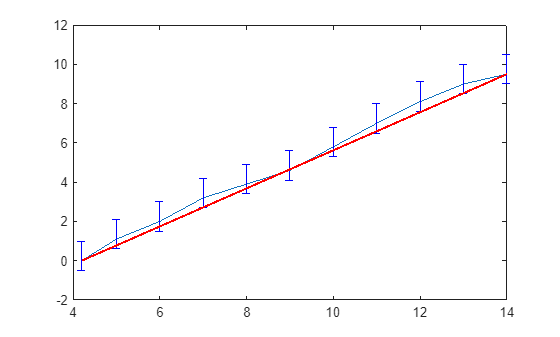

x = [4.2 5.0 6.0 7.0 8.0 9.0 10.0 11.0 12.0 13.0 14.0]; % [cm]
force = [0.0 1.1 2.0 3.2 3.9 4.6 5.8 7.0 8.1 9.0 9.5]; % [N]

figure()
plot(x,force);
hold on
errorbar(x,force,0.5,1, "blue");
plot([x(1) x(end)], [force(1) force(end)], "red", 'LineWidth', 1.5);

## Exercise 6: Animation

On va créer un champ de vecteurs sur une grille.

Créer deux vecteurs ligne x et y allant de 1 à 11 par pas de 2.

Créer deux matrices u et v représentant les composantes selon x et selon y d'un champ de vitesse, sachant que tous les vecteurs sont identiques avec une composante u à 0.2 et une composante v à 0.

Afficher le champ de vecteurs (utilisation de quiver), augmenter l'épaisseur des traits et changer la couleur avec une couleur créée par vous (voir aide ColorSpec). 

On va créer une petite animation de 20 images. Pour chaque image, on va changer la valeur de u en ajoutant un nombre réel positif ou négatif choisi aléatoirement entre 0 et 1 et idem pour v.

Utiliser la fonction pause (voir aide) pour visualiser votre animation.

Après l'affichage de votre première figure initiale, attendre que l'utilisateur appuie sur une touche pour continuer et lancer votre animation de 20 images.

Changer la couleur des vecteurs à chaque image de l'animation de façon aléatoire

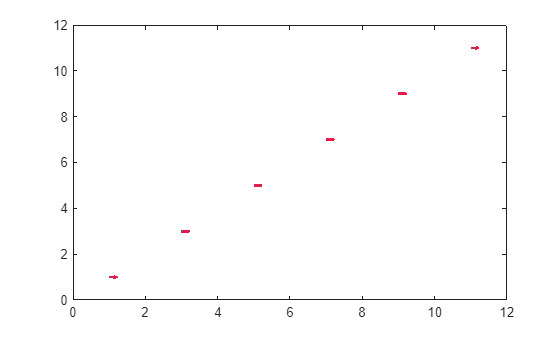

x = 1:2:11;
y = x;
u = 0.2 * ones([1 6]);
v = zeros([1 6]);
figure()
quiver(x,y,u,v, 0, LineWidth=2, Color="#e01d4b")

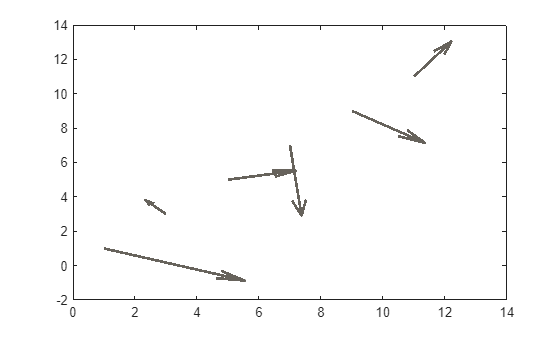

for i = 1:20
    u = u + rand(1, 6) * 2 - 1;
    v = v + rand(1, 6) * 2 - 1;
    quiver(x, y, u, v, 0, 'LineWidth', 2, 'Color', rand(1, 3));
    pause(0.5);
end